# What is a Function?

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

**function/mapping**: a mapping (also called a function) is a rule that assigns to every element x of a set X a single element of a set Y. It is written as: 


$$f:X\rightarrow Y$$
 

where the arrow indicates mapping, and the letter $f$ symbolically specifies a rule of mapping. When we write:


$$y=f(x)$$


we are mapping from argument $x$ in domain $X$ to value $y$ in co-domain Y.

***Definitions:***

- **domain**: big $X$ is the domain of $f$

- **argument**: little $x$ is an element in big $X$, an argument of the function $f$.

- **co-domain**: big $Y$ is the co-domain of $f$.

- **image/value**: when $y =f(x)$, we refer to $y$ as the image or value of $x$ under $f$.

- **range**: $f(X) = \{ y \in Y : y = f(x) \text{ for some } x \in X  \}$

- **graph: **"The graph of a function of one variables consists of all points in the Cartesian plane whose coordinates (x,y) satisfy the equation y = f(x)" (SB)

In some textbooks, $x$ is called independent or exogenous variables, and $y$ is called dependent or endogenous variables. We will avoid using those words to avoid confusion.

***This is a function***:

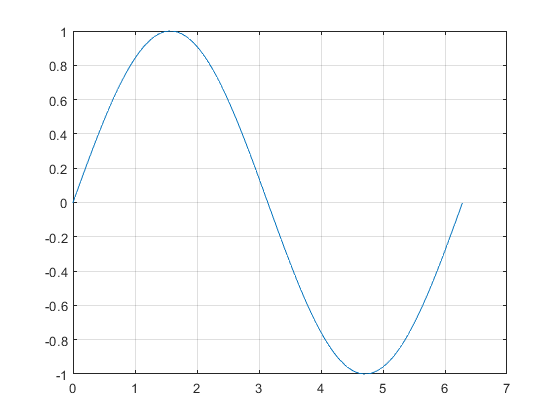

figure();
x = 0:pi/100:2*pi;
y = sin(x);
plot(x,y);
grid on;

***This is NOT a function***:

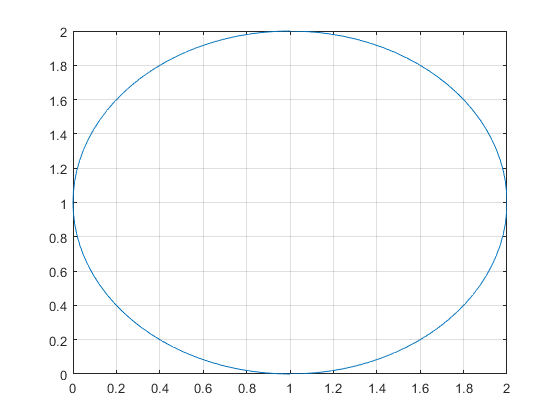

figure();
x = 1; y=1; r=1;
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
grid on;

**A Linear Function**

A linear function, polynomial of degreee 1, has slope $m$ and intercept $b$. Linear functions have a constant slope.

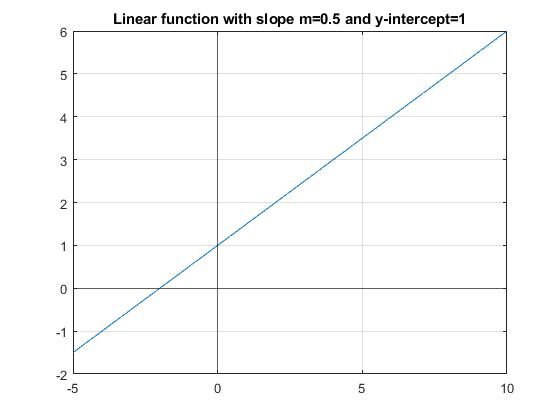

figure();
m = 0.5;
b = 1;
ar_x = linspace(-5, 10, 100);
ar_y = ar_x*m + b;
h = plot(ar_x, ar_y);
% Title
title({['Linear function with slope m=' num2str(m) ' and y-intercept=' num2str(b)]});
% axis lines
xline0 = xline(0);
xline0.HandleVisibility = 'off';
yline0 = yline(0);
yline0.HandleVisibility = 'off';
grid on;